57-Bus State Estimation

clear all
clc
rng('default');
rng(1);
Tolerance= 0.001;
Count_Max=10;
Count=0; 
Flag=1;

%read in data 
Bus_data = 'Data 57 bus.xlsx'

Bus_data = 'Data 57 bus.xlsx'

T = readtable(Bus_data);


%P = Pgen - Pload
Real_power= T(1:57, 'MW');
P = table2array(Real_power);
%P = P + 0.05*wgn(57,1, 0)

%Q = Qgen - Qload
Reactive_power= T(1:57, 'MVAR');
Q = table2array(Reactive_power);
%Q = Q + 0.05*wgn(57,1, 0)

%voltage - measured values 
Voltage = T(1:57, 'FinalV');
Vx = table2array(Voltage);
 
truev = T(1:57, 'FinalV');
V_true = table2array(truev);

%%true angle values 
trueo = T(1:57, 'FinalA');
O_true = table2array(trueo);
O_true = deg2rad(O_true);

ii =[1	2	3	4	4	6	6	8	9	9	9	9	13	13	1	1	1	3	4	4	5	7	10	11	12	12	12	14	18	19	21	21	22	23	24	24	24	26	27	28	7	25	30	31	32	34	34	35	36	37	37	36	22	11	41	41	38	15	14	46	47	48	49	50	10	13	29	52	53	54	11	44	40	56	56	39	57	38	38	9];
jj = [2	3	4	5	6	7	8	9	10	11	12	13	14	15	15	16	17	15	18	18	6	8	12	13	13	16	17	15	19	20	20	22	23	24	25	25	26	27	28	29	29	30	31	32	33	32	35	36	37	38	39	40	38	41	42	43	44	45	46	47	48	49	50	51	51	49	52	53	54	55	43	45	56	41	42	57	56	49	48	55];

admit_mat;

Solve for 'true' real and reactive power flow values 

x = 1; n = 80; 
m =1; Pij_true = 0;
Pij_true_col =zeros(80,1);

while x<=n
      Pij_true = V_true(ii(x))^2*G(ii(x),jj(x))-V_true(ii(x))*V_true(jj(x))*(G(ii(x),jj(x))*cos(O_true(ii(x))-O_true(jj(x)))+B(ii(x),jj(x))*sin(O_true(ii(x))-O_true(jj(x))));
      Pij_true_col(m) = Pij_true;      
      x = x+1;
      m = m+1;
end
Pij_true_col;

x = 1; n = 80; Qij_true = 0;
Qij_true_col =zeros(80,1);

while x<=n
      Qij_true = -V_true(ii(x))^2*B(ii(x),jj(x))-V_true(ii(x))*V_true(jj(x))*(G(ii(x),jj(x))*sin(O_true(ii(x))-O_true(jj(x)))-B(ii(x),jj(x))*cos(O_true(ii(x))-O_true(jj(x))));
      Qij_true_col(x) = Qij_true;      
      x = x+1;
end
Qij_true_col;

Input 'bad data' here

%P(6) = 5; Q(6) = 5; Pij_true_col(6) = 5; Qij_true_col(6) = 5

57-bus network (1 slack, 6 PV, 50 PQ)

%initialise phase and voltage values - flat start
angles = zeros([1 56]); %all busses minus slack 
voltages = ones([1 50]); %50 PQ buses 

x_new = [angles voltages]'; 

while( Flag==1 && Count < Count_Max)
Count=Count+1;
O = [0 x_new(1:56)'];
V = [Vx(1) Vx(2) Vx(3) (x_new(57:58))' Vx(6) x_new(59) Vx(8) Vx(9) (x_new(60:61))' Vx(12) (x_new(62:106))'];


%Real power injection
N = 57; %no. busses 
i = 2; %row of admittance matrix
j = 1; %column of admittance matrix 
m= 1; %count for P_list index
P_List =zeros(56,1);
P_inj = 0.0;

while i<=N
     while j<=N
        P_inj = P_inj + V(i)*mag(i,j)*V(j)*cos(O(i)-O(j)-theta(i,j));
        j=j+1;
     end 
        P_List(m) = P_inj;
        P_inj = 0.0;        j = 1;        i=i+1;         m = m+1;
end
P_List;

%Reactive power injection
i = 4; j=1; m= 1; Q_inj = 0.0;
Q_List =zeros(54,1);

while i<=N
    while j<=N
        Q_inj = Q_inj + (V(i)*mag(i,j)*V(j)*sin(O(i)-O(j)-theta(i,j)));
        j=j+1;
    end
        Q_List(m) = Q_inj;
        Q_inj = 0.0;         j = 1;        i=i+1;        m = m+1; 
end

Q_List=[Q_List(1:2)' Q_List(4) Q_List(7:8)' Q_List(10:54)']';


%Real power flow 
x = 1; n = 80; Pij = 0;
Pij_col =zeros(80,1);

while x<=n
      Pij = V(ii(x))^2*G(ii(x),jj(x))-V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
      Pij_col(x) = Pij;      
      x = x+1;
end
Pij_col;

%Reactive power flow
x = 1; n = 80; Qij = 0;
Qij_col =zeros(80,1);

while x<=n
      Qij = -V(ii(x))^2*B(ii(x),jj(x))-V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
      Qij_col(x) = Qij;      
      x = x+1;
end
Qij_col;

%measurement function h(x)
h = [P_List; Pij_col; Q_List; Qij_col];


Jacobian Matrix

%first section of Jacobian dP/dO
i = 2; %index for P [P2-P57]
k = 2; %index for angle [O2-O57]
j=1;%index for count 
N = 57; %no. busses 
P_O_col =zeros(3136,1); %56*56 
m = 1; P_O=0.0;
while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                P_O = P_O-(V(i)*V(j)*mag(i,j)*sin(O(i)-O(j)-theta(i,j)));
                j = j+1;
            end
            P_O = P_O + (V(i)*mag(i,i)*V(i)*sin(O(i)-O(i)-theta(i,i)));
            P_O_col(m) = P_O;            j=1;             P_O = 0.0;
        elseif (i~=k)
             P_O = V(i)*V(k)*mag(i,k)*sin(O(i)-O(k)-theta(i,k));
             P_O_col(m) = P_O;              P_O = 0.0; 
        end
       i = i+1;        m = m+1;
    end 
   k = k+1;    i=2;
end
P_O_col; 
P_O_reshape = reshape(P_O_col,[56,56]);

%second section of Jacobian dQ/dO
i = 4; k = 2; j=1; N = 57; m =1; Q_O=0.0;
Q_O_col = zeros(3024,1); %54 x 56

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                Q_O = Q_O +V(i)*mag(i,j)*V(j)*cos(O(i)-O(j)-theta(i,j));
                j = j+1;
            end
            Q_O = Q_O-(V(i)*mag(i,i)*V(i)*cos(O(i)-O(i)-theta(i,i)));
            Q_O_col(m) = Q_O;             j=1; 
            Q_O = 0.0;
        elseif (i~=k)
             Q_O = -V(i)*V(k)*mag(i,k)*cos(O(i)-O(k)-theta(i,k));
             Q_O_col(m) = Q_O;              Q_O = 0.0;
        end
       i = i+1;        m=m+1;
    end  
   k = k+1;    i=4;
end
Q_O_col; 
Q_O_reshape = reshape(Q_O_col,[54,56]);
Q_O_reshape(3,:)=[]; %6
Q_O_reshape(4,:)=[]; %8
Q_O_reshape(4,:)=[]; %9
Q_O_reshape(6,:)=[]; %12
Q_O_reshape;


%third section of Jacobian dP/dV
i = 2; k = 4; j=1; N = 57; 
P_V_col = zeros(3024,1); %54*56
m=1; P_V=0.0;

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                P_V = P_V +mag(i,j)*abs(V(j))*cos(O(i)-O(j)-theta(i,j));
                j = j+1;
            end
            P_V = P_V+V(i)*mag(i,i)*cos(theta(i,i));
            P_V_col(m) = P_V;
            P_V = 0.0;
            j=1; 
        elseif (i~=k)
             P_V = V(i)*mag(i,k)*cos(O(i)-O(k)-theta(i,k));
             P_V_col(m) = P_V;
             P_V = 0.0;
        end
       i = i+1;
       m = m+1;       
    end 
   k = k+1;
   i=2;
end
P_V_col; 
P_V_reshape = reshape(P_V_col,[56,54]);
P_V_reshape(:,3)=[];
P_V_reshape(:,4)=[];
P_V_reshape(:,4)=[];
P_V_reshape(:,6)=[];
P_V_reshape;


%fourth section of Jacobian dQ/dV
i = 4; k = 4; j=1; N = 57; 
Q_V_col = zeros(2916,1); %54 x 54
m=1; Q_V=0.0;

while k<=N    
    while i<=N
        if (i==k)
            while j<=N
                Q_V = Q_V +(mag(i,j)*V(j)*sin(O(i)-O(j)-theta(i,j)));
                j = j+1;
            end
            Q_V = Q_V-V(i)*mag(i,i)*sin(theta(i,i));
            Q_V_col(m) = Q_V;
            Q_V = 0.0;
            j=1; 
        elseif (i~=k)
             Q_V = V(i)*mag(i,k)*sin(O(i)-O(k)-theta(i,k));
             Q_V_col(m) = Q_V;
             Q_V = 0.0;
        end
       i = i+1;  
       m = m+1;
    end 
   k = k+1;
   i=4;
end
Q_V_col;
Q_V_reshape = reshape(Q_V_col,[54,54]);
Q_V_reshape(3,:)=[];
Q_V_reshape(4,:)=[];
Q_V_reshape(4,:)=[]; 
Q_V_reshape(6,:)=[]; 
Q_V_reshape(:,3)=[];
Q_V_reshape(:,4)=[];
Q_V_reshape(:,4)=[];
Q_V_reshape(:,6)=[];
Q_V_reshape;


%fifth section of Jacobian dPF/dO
x = 1; k = 2; N=57; n = 80; 
PF_O_col =zeros(4480,1); %80*56
m = 1; PF_O=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            PF_O = V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));       
            PF_O_col(m) = PF_O;             PF_O = 0.0;
    elseif (jj(x)==k)
             PF_O = -V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
             PF_O_col(m) = PF_O;              PF_O = 0.0;
    else
             PF_O = 0;              PF_O_col(m) = PF_O;
    end 
    m = m+1;     k = k+1;
end
k = 2; x = x+1;
end
PF_O_col ;
PF_O_reshape = reshape(PF_O_col,[56,80]);
PF_O_reshape = transpose(PF_O_reshape);

%sixth section of Jacobian dPF/dV
x = 1; k = 4; N=57; n = 80; 
PF_V_col =zeros(54*80,1); m = 1; PF_V=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            PF_V = -V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))))+2*(G(ii(x),jj(x)))*V(ii(x));
            PF_V_col(m) = PF_V;
            PF_V = 0.0;
    elseif (jj(x)==k)
             PF_V = -V(ii(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
             PF_V_col(m) = PF_V;              PF_V = 0.0;
    else
             PF_V = 0;              PF_V_col(m) = PF_V;
    end 
    m = m+1;     k = k+1;
end
k = 4; x = x+1;
end
PF_V_col;
PF_V_reshape = reshape(PF_V_col,[54,80]);
PF_V_reshape = transpose(PF_V_reshape);
PF_V_reshape(:,3)=[];
PF_V_reshape(:,4)=[];
PF_V_reshape(:,4)=[];
PF_V_reshape(:,6)=[];
PF_V_reshape;

%seventh section of Jacobian dQF/dO
x = 1; k = 2; N=57; n = 80; 
QF_O_col =zeros(80*56,1);
m = 1; QF_O=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            QF_O = -V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
            QF_O_col(m) = QF_O;             QF_O = 0.0;
    elseif (jj(x)==k)
             QF_O = V(ii(x))*V(jj(x))*(G(ii(x),jj(x))*cos(O(ii(x))-O(jj(x)))+B(ii(x),jj(x))*sin(O(ii(x))-O(jj(x))));
             QF_O_col(m) = QF_O;              QF_O = 0.0;
    else
             QF_O = 0;              QF_O_col(m) = QF_O;
    end 
    m = m+1;     k = k+1;
end
k = 2; x = x+1;
end
QF_O_col;
QF_O_reshape = reshape(QF_O_col,[56,80]);
QF_O_reshape = transpose(QF_O_reshape);

%eigth section of Jacobian dQF/dV
x = 1; k = 4; N=57; n = 80; 
QF_V_col =zeros(54*80,1); 
m = 1; QF_V=0.0;
while x<=n
while k<=N    
    if (ii(x)==k)
            QF_V = -V(jj(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))))-2*(B(ii(x),jj(x)))*V(ii(x));
            QF_V_col(m) = QF_V;
            QF_V = 0.0;
    elseif (jj(x)==k)
             QF_V = -V(ii(x))*(G(ii(x),jj(x))*sin(O(ii(x))-O(jj(x)))-B(ii(x),jj(x))*cos(O(ii(x))-O(jj(x))));
             QF_V_col(m) = QF_V;             QF_V = 0.0; 
    else
             QF_V = 0;             QF_V_col(m) = QF_V;
    end 
    m = m+1;    k = k+1;
end
k = 4;x = x+1;
end
QF_V_col; 
QF_V_reshape = reshape(QF_V_col,[54,80]);
QF_V_reshape = transpose(QF_V_reshape);
QF_V_reshape(:,3)=[];
QF_V_reshape(:,4)=[];
QF_V_reshape(:,4)=[];
QF_V_reshape(:,6)=[];
QF_V_reshape;


J = [P_O_reshape P_V_reshape; PF_O_reshape PF_V_reshape; Q_O_reshape Q_V_reshape; QF_O_reshape QF_V_reshape];


Covariance Matrix

e = 3*10^(-2);
error = repmat(e,1, 266);
R = diag(error);

Gain Matrix

Gain = J'*R^(-1)*J;

Measured values

P_meas = P(2:57);
Q_req = Q(4:57);
Q_meas = [Q_req(1:2)' Q_req(4)' Q_req(7:8)' Q_req(10:54)']';

y = [P_meas; Pij_true_col; Q_meas; Qij_true_col];

Update state vector

delta_x = Gain^(-1)*J'*R^(-1)*(y-h);

x_new = x_new + delta_x;

%Mismatch 
Mismatch = max(abs(delta_x));

%If Mismatch>Tolerance, restart SE
if (Mismatch> Tolerance)
    
Flag = 1;
else
    Flag = 0;
end

end

%change phases from rad to degrees 
angles_deg = rad2deg(x_new(1:56));

%Final state vector outputs 
final= [0 angles_deg' V(1) V(2) V(3) x_new(57:58)' V(6) x_new(59)' V(8) V(9) (x_new(60:61))' V(12) (x_new(62:106))']

final =          0   -1.1760   -5.9255   -7.2316   -8.5126   -8.6593   -7.6000   -4.4818   -9.5902  -11.4247  -10.1800  -10.4770   -9.7876   -9.3708   -7.1525   -8.8420   -5.3739  -13.1360  -13.6157  -13.5234  -12.9020  -12.8343  -12.8984  -13.2320  -18.0827  -12.9268  -11.5105  -10.4857   -9.7741  -18.7572  -19.4841  -18.5420  -18.5827  -14.0889  -13.8446  -13.5784  -13.3954  -12.7003  -13.4432  -13.6043  -14.0265  -15.4827  -11.3281  -11.8247   -9.2246  -11.3688  -12.5308  -12.6006  -12.9017  -13.3802



Final_tolerance = Mismatch;

%print no. iterations
Count

Count = 3

Plots 

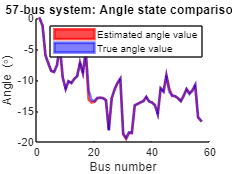

x_axis = linspace(1, 57,57);
y1 = final(1:57);
y2 = rad2deg(O_true);

figure
hold on

p1 = patchline(x_axis,y1, 'facecolor',[1 0 0],'edgecolor',[1 0 0], 'LineWidth', 2, 'edgealpha',0.7, 'facealpha',0.7);
p2 = patchline(x_axis,y2, 'facecolor',[0 0 1],'edgecolor',[0 0 1], 'LineWidth', 2, 'edgealpha',0.5, 'facealpha',0.5);

title('57-bus system: Angle state comparison');
xlabel('Bus number'); 
ylabel('Angle (\circ)');
legend({'Estimated angle value', 'True angle value'}, 'Location', 'northeast')
hold off

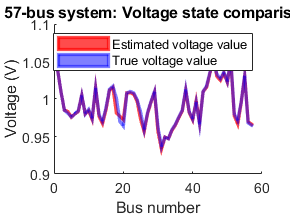


y1 = final(58:114);
y2 = V_true;

figure
hold on
p1 = patchline(x_axis,y1, 'facecolor',[1 0 0],'edgecolor',[1 0 0], 'LineWidth', 2, 'edgealpha',0.7, 'facealpha',0.7);
p2 = patchline(x_axis,y2, 'facecolor',[0 0 1],'edgecolor',[0 0 1], 'LineWidth', 2, 'edgealpha',0.5, 'facealpha',0.5);

ylim([0.9 1.1])
title('57-bus system: Voltage state comparison');
xlabel('Bus number'); 
ylabel('Voltage (V)');
legend({'Estimated voltage value', 'True voltage value'}, 'Location', 'northeast')

hold off